## Step 1: Define System and Parameters    

clear all; clc
% True system parameters (unknown to the algorithm)
A_true = [0 1; -1 -0.5]; % True system matrix A (unknown to the algorithm)
B_true = [0; 1];         % True input matrix B (unknown to the algorithm)

% Cost function matrices
Q = eye(2);         % State weighting matrix
R = 1;              % Control weighting matrix

% Time step for real-time operation
dt = 0.01;          % Time step size

% Simulation time
tspan = 0:dt:10;    % Simulation time span

% Initial state
x0 = [1; 0];        % Initial state vector

## Step 2: Define The System Dynamics  

% System dynamics (unknown to the algorithm)
sys_dynamics = @(t, x, u) A_true * x + B_true * u;         

## Step 3: Define the Cost Function                  

% Cost function
cost_function = @(x, u) x' * Q * x + u' * R * u;

## Step 4 Initialize Policy and Value 

% Initial control policy (e.g., random or zero)
K = [0 0];          % Initial control gain matrix

% Initial value function parameters (e.g., zero)
P = zeros(2, 2);    % Initial value function matrix

## Step 5: Collect Data for system **Identification **

% Collect input-output data to estimate A and B
N = 1000;           % Number of data points
t_data = linspace(0, 1, N); % Time points for data collection
x_data = zeros(2, N); % State data
u_data = zeros(1, N); % Input data

% Simulate the system with random inputs to collect data
x_current = x0;     % Initialize the state
for i = 1:N
    u_data(i) = randn; % Random input
    [~, x] = ode45(@(t, x) sys_dynamics(t, x, u_data(i)), [0 dt], x_current);
    x_data(:, i) = x(end, :)';
    x_current = x(end, :)'; % Update the current state
end

% Estimate A and B using least squares
X_dot = diff(x_data, 1, 2) / dt; % Approximate derivative of x
X = x_data(:, 1:end-1);         % State data
U = u_data(1:end-1);            % Input data
Phi = [X; U];                   % Combined state and input data
Theta = X_dot / Phi;            % Least squares estimate of [A B]

% Extract A and B from Theta
A_est = Theta(:, 1:2);          % Estimated A
B_est = Theta(:, 3);             % Estimated B

To estimate $A,B$, 

   - Batch type Least square is used. the control input is used a gaussian random. 

  - sampling time: $\textrm{dt}$

  - duration time: $N\times \textrm{dt}$  $A,B$ are estimated to get $A_{\textrm{est}\;} ,B_{\textrm{est}}$ 

  - control input : a gaussian random

  - measurement data: $\left\lbrack X;U\right\rbrack =\left\lbrack \left(x_{1i} \;,x_{2i\;} \right),u_{i\;} ,\right\rbrack ,\;\;\;i=1,\ldotp \ldotp \ldotp ,N$,  

Results

  - $A_{\textrm{est}\;} ,B_{\textrm{est}}$

  - the final state after indentification: $x_{\textrm{current}}$

## **Step 6: Real-Time IRL  **

% IRL parameters
alpha = 0.01;       % Learning rate
exploration_noise = 0.1; % Exploration noise (e.g., Gaussian noise)

% Initialize state and time
% x = x0;           % Initial state
x = x_current;      % Initial state (final state from system identification)

x_history = zeros(2, length(tspan)); % To store state history
u_history = zeros(1, length(tspan)); % To store control history

% Main real-time IRL loop
for i = 1:length(tspan)
    % Current time
    t = tspan(i);
    
    % Apply control input with exploration noise
    u = -K * x + exploration_noise * randn;     % Add exploration noise
    %u = -K * x;                                % Add exploration noise
    u_history(i) = u;
    
    % Simulate the system for one time step
    x_dot = sys_dynamics(t, x, u);
    x_next = x + x_dot * dt;
    
    % Compute the reward
    r = cost_function(x, u);
    
    % Update the value function parameters (P)
    delta = r + x_next' * P * x_next - x' * P * x;
    P = P + alpha * delta;
    
    % Update the control policy (K) using the estimated B
    K = inv(R) * B_est' * P;
    
    % Update the state
    x = x_next;
    x_history(:, i) = x;
end

Given $A_{\textrm{est}\;} ,B_{\textrm{est}\;}$, the value is ${V\left(x\right)\;=\;x}^T \textrm{Px}\;$,which is  the solution of DARE, to get $P$

using Value Iteration method

    value evaluation                  $P\gets P+\alpha \;\left(r_{\;\;} +\gamma \left(x_{\left(k+1\right)}^{T\;} {\textrm{Px}}_{\left(k+1\right)} -x_k^T {\textrm{Px}}_{k\;} \right)\;\right)$

    policy update (feedback gain)            $K\;=R^{-1\;} B_{\textrm{est}\;}^{T\;} P$

    optimal policy :                                     $u=-\textrm{Kx}+\eta \bullet \textrm{randn}$            

- Here, $A_{\textrm{est}\;} \;$ is not used, but $B_{\textrm{est}}$

-   Discount factor $\gamma =1$

  ?  ***Why add some noise into the optimal policy? they say "exploration noise"*** 

## Step 7 : Plot the Results 

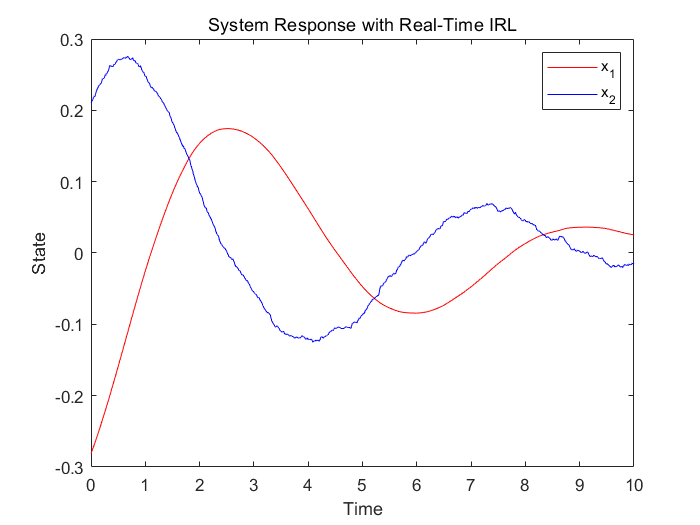


% Plot the results
figure;
plot(tspan, x_history(1, :), 'r', tspan, x_history(2, :), 'b');
xlabel('Time');
ylabel('State');
legend('x_1', 'x_2');
title('System Response with Real-Time IRL');

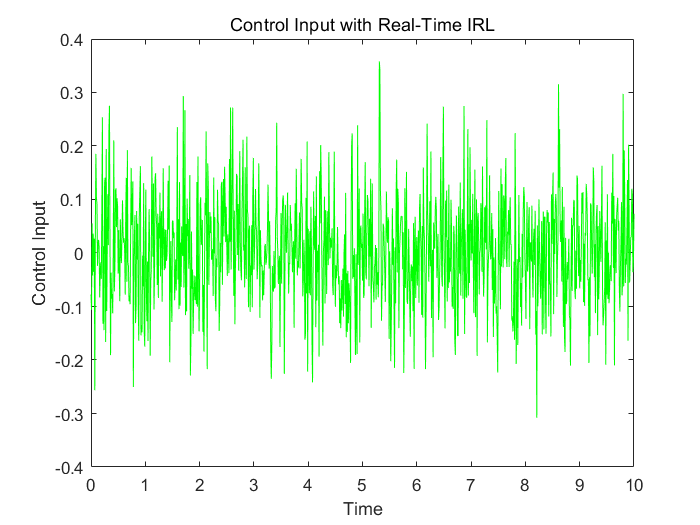


% Plot the control input
figure;
plot(tspan, u_history, 'g');
xlabel('Time');
ylabel('Control Input');
title('Control Input with Real-Time IRL');

- plot the total trojectory from identification to IRL

- during IRL compare the optimal control with / without noise.